# Module 4 Practice 1

## Analyze Puzzle Region Shape

In an image with many areas of puzzle pieces, find those with three pieces specifically connected in a straight line vs. right angle. 

For this problem your code will need to do the following: 

- Create a mask which will segment only the regions consisting of 3 joined puzzle pieces (use region filtering to modify the mask created by the provided function). Assign your answer to the variable name `threePieceMask`. 

- Calculate the [Area and Eccentricity](https://www.mathworks.com/help/images/ref/regionprops.html#buoixjn-1-properties) of each region in `threePieceMask`. Provide the results in a table variable `threePieceProperties`. 

- Filter the `threePieceMask` to include only the regions with three pieces connected in a straight line. Assign the result to `threePieceLinearMask`. **Hint:** You can use thresholds for [Eccentricity](https://www.mathworks.com/help/images/ref/regionprops.html#buoixjn-1-properties) with the [bwpropfilt](https://www.mathworks.com/help/images/ref/bwpropfilt.html) function to isolate the straight-line connected regions in `threePieceMask`. 

- Find the coordinates of a bounding box for each of the regions in `threePieceLinearMask`. Provide the results in a table variable `threePieceLinearBoxes`. **Hint:** Use the `regionprops` function on `threePieceLinearMask` with the syntax shown in [this example](https://www.mathworks.com/help/images/ref/regionprops.html#buoogbr-1), and the `BoundingBox` [property](https://www.mathworks.com/help/images/ref/regionprops.html#buoixjn-1-properties). 

- To apply the bounding boxes to the original image and see the results, uncomment the provided template code. 

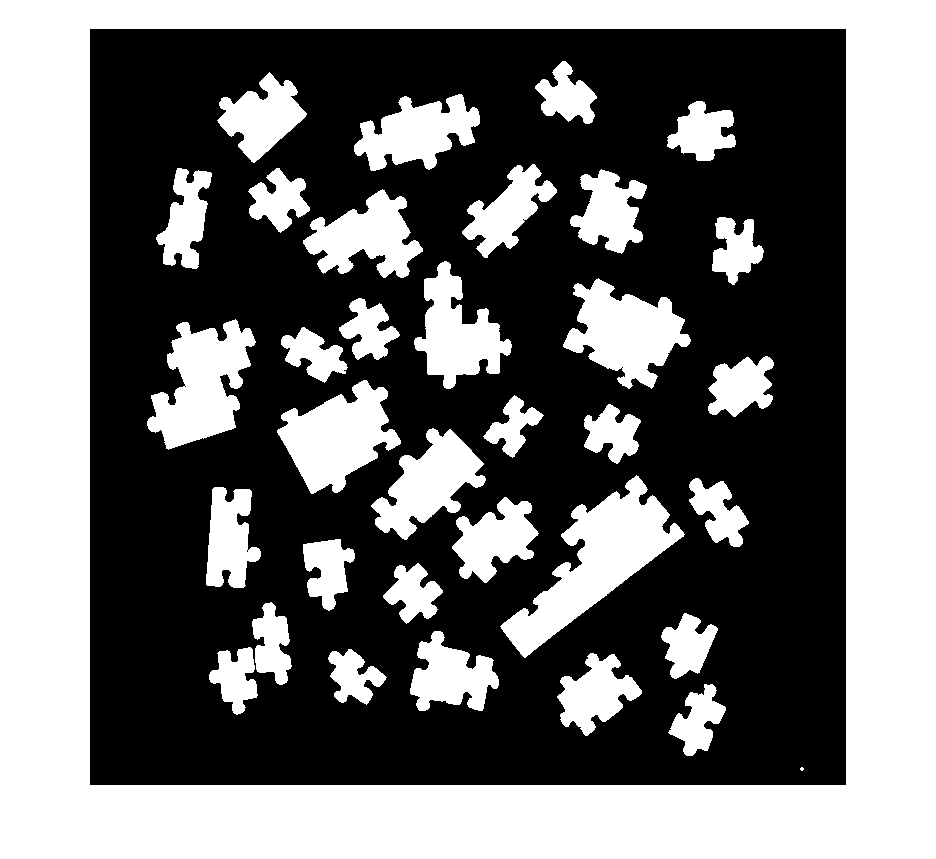

puzzleImage = imread("Puzzle_34.jpg"); 
puzzleMask = segmentPuzzle34(puzzleImage); 
imshow(puzzleMask)

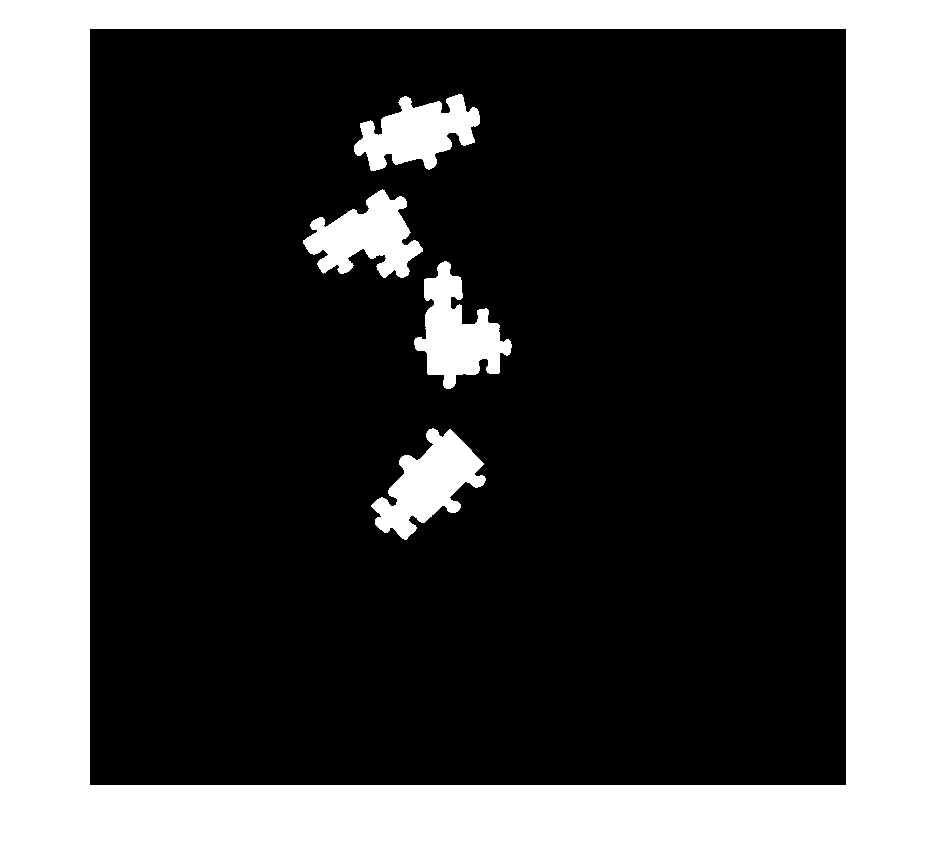

[threePieceMask, threePieceProperties] = filter3PieceRegions(puzzleMask);
imshow(threePieceMask)

threePieceProperties

threePieceProperties = 4×2 table
    Area     Eccentricity
    _____    ____________

    22910      0.74784   
    22326      0.88239   
    24512      0.85229   
    24137      0.72916   


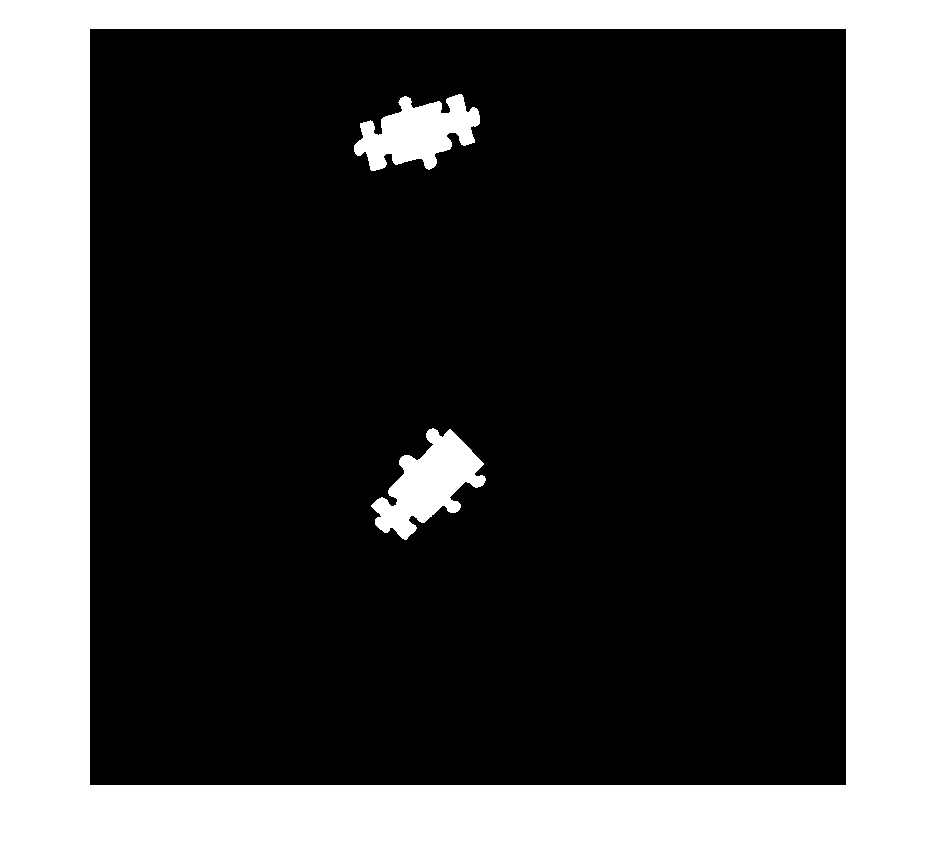

[threePieceLinearMask, threePieceLinearProperties] = filter3PieceLinearRegions(threePieceMask);
imshow(threePieceLinearMask)

threePieceLinearBoxes = regionprops("table", threePieceLinearMask, "BoundingBox")

threePieceLinearBoxes = 2×1 table
              BoundingBox           
    ________________________________

    528.5    130.5      253      155
    563.5    799.5      229      224


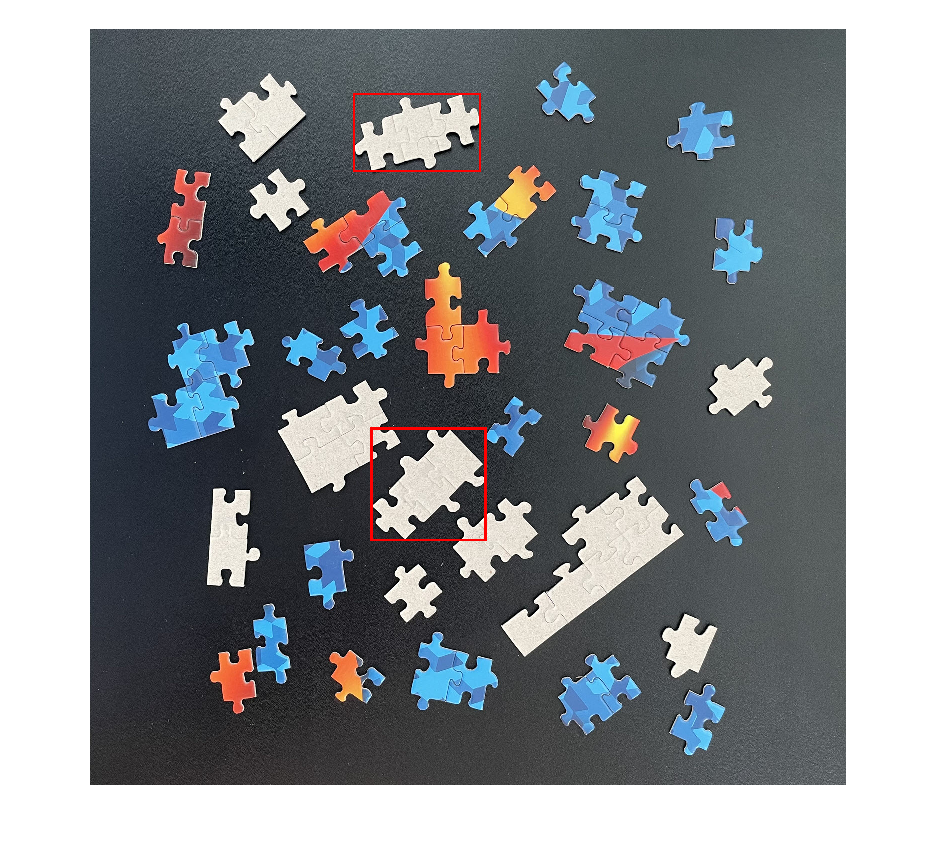

puzzleImageBoxed = insertShape(puzzleImage,"Rectangle",threePieceLinearBoxes.BoundingBox,"color","red","LineWidth",5); 
figure, imshow(puzzleImageBoxed);

function [BW_out,properties] = filter3PieceRegions(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 21-Jun-2024
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[20000, 30000]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Eccentricity'});

properties = struct2table(properties);

end

function [BW_out,properties] = filter3PieceLinearRegions(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 21-Jun-2024
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Eccentricity',[0.8, 1]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Eccentricity', 'MajorAxisLength', 'MinorAxisLength', 'Perimeter'});

properties = struct2table(properties);

end

function [BW,maskedImage] = segmentPuzzle34(X)
%segmentImage Segment image using auto-generated code from imageSegmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the imageSegmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 29-Aug-1997
%----------------------------------------------------

X = im2gray(X); 

% Adjust data to span data range.
X = imadjust(X);

% Threshold image - adaptive threshold
BW = imbinarize(X, 'adaptive', 'Sensitivity', 0.500000, 'ForegroundPolarity', 'bright');

% Erode mask with disk
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imerode(BW, se);
% BW = bwpropfilt(BW,"Area",[300,inf]);

% Dilate mask with disk
radius = 4; 
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imdilate(BW, se);

% Clear borders
BW = imclearborder(BW);

% Fill holes
BW = imfill(BW, 'holes');

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end